t = load("t.txt");
x = transpose(load("x.txt")); % x(t) = A + B*t + C*sin(2*pi*t) + w(t)

Lineær modell / BLUE, 1b)

H = [ones(length(t), 1), t(:), sin(2*pi*t(:))];
H_T=transpose(H);

S=inv((H_T*H))*H_T*x;  % [A ; B ; C]
CRLB=diag(inv(H_T*H)); % [Var(A) ; Var(B) ; Var(C)]

x_est=transpose(S(1)+S(2)*t+S(3)*sin(2*pi*t));
x_true=transpose(1+2*t+3*sin(2*pi*t));

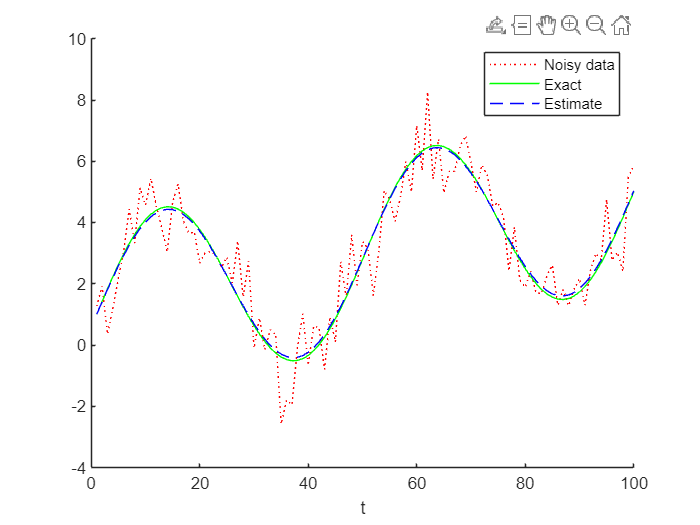

figure;
hold on;
plot(x,":","Color","r");
plot(x_true,"Color","g");
plot(x_est,"--","Color","b");
xlabel("t")
legend("Noisy data","Exact","Estimate");

Maximum likelihood, 2b)

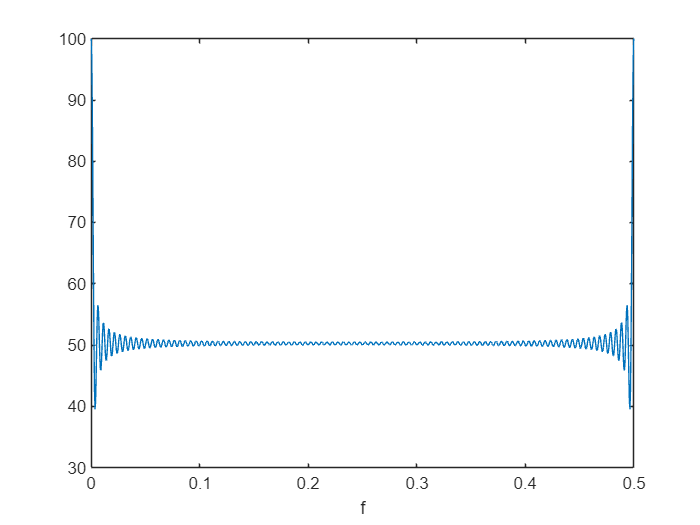

N=100;
n=0:N-1;
f=linspace(0,0.5,1000);
F=zeros(1,length(f));
for i = 1:length(f)
  F(i)=sum(cos(2*pi*f(i)*n).^2);
end

figure;
plot(f,F);
xlabel("f")

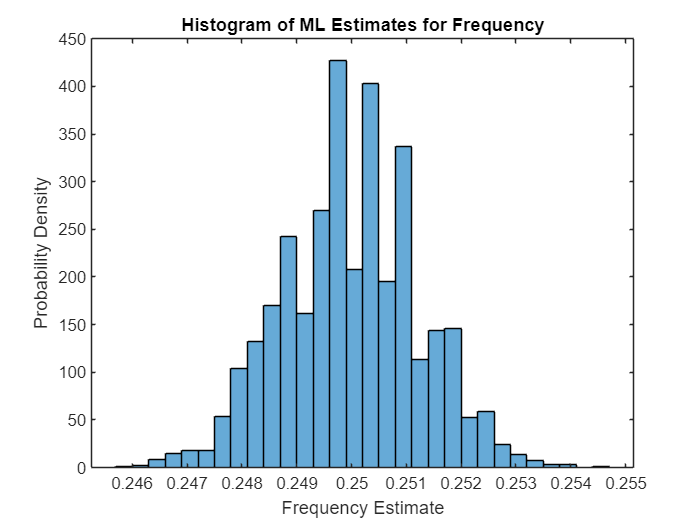

N = 10;         % Number of samples
f_true = 0.25;  % True frequency
sigma_2 = 0.01; % Variance of the noise
M = 5000;       % Number of realizations
delta_f = 0.0001; % Step size for frequency grid search

% Generate realizations and compute ML estimates
f_estimates = zeros(1, M);
for i = 1:M
    % Generate observed data
    n = 0:N-1;
    w = sqrt(sigma_2) * randn(1, N);
    x = cos(2*pi*f_true*n) + w;
    
    % Perform grid search
    likelihoods = zeros(1, round(0.5/delta_f));
    for j = 1:length(likelihoods)
        f = delta_f * j;
        likelihoods(j) = prod(1/sqrt(2*pi*sigma_2) * exp(-(x - cos(2*pi*f*n)).^2 / (2*sigma_2)));
    end
    
    % Find ML estimate
    [~, max_index] = max(likelihoods);
    f_estimates(i) = delta_f * max_index;
end

% Plot histogram of ML estimates
figure;
histogram(f_estimates, 'Normalization', 'pdf');
xlabel('Frequency Estimate');
ylabel('Probability Density');
title('Histogram of ML Estimates for Frequency');

Bayesian estimator

e1=1/2;
e2=3/4;
x_bay=4;
lim=2*x_bay

lim = 8

theta=-lim:1/20:lim;
p1=e1*normpdf(theta,x_bay,1)+(1-e1)*normpdf(theta,-x_bay,1)

p1 =     0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0006    0.0007    0.0009    0.0010    0.0012    0.0014    0.0016    0.0019    0.0022    0.0026    0.0030    0.0034    0.0040    0.0045    0.0052    0.0060    0.0068    0.0077    0.0088    0.0099    0.0112    0.0126    0.0142    0.0159    0.0177    0.0198    0.0220    0.0244    0.0270    0.0298    0.0328    0.0360    0.0395    0.0431    0.0470    0.0511    0.0555    0.0600


p2=e2*normpdf(theta,x_bay,1)+(1-e2)*normpdf(theta,-x_bay,1)

p2 =     0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0006    0.0007    0.0008    0.0010    0.0011    0.0013    0.0015    0.0017    0.0020    0.0023    0.0026    0.0030    0.0034    0.0039    0.0044    0.0050    0.0056    0.0063    0.0071    0.0079    0.0089    0.0099    0.0110    0.0122    0.0135    0.0149    0.0164    0.0180    0.0197    0.0216    0.0235    0.0256    0.0277    0.0300


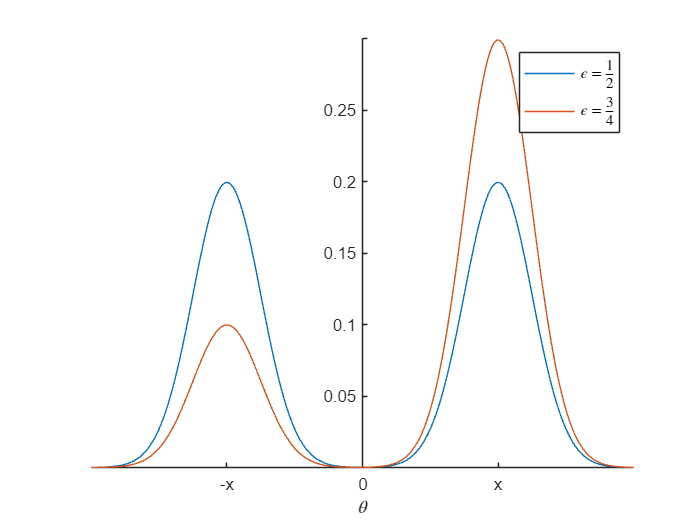


figure;
ax = gca;
ax.YAxisLocation = 'origin';
hold on;
plot(theta,p1);
plot(theta,p2);
xticks([-x_bay, 0, x_bay]); xticklabels(["-x",0,"x"]);
xlabel("$\theta$","Interpreter","latex");
legend("$\epsilon=\frac{1}{2}$","$\epsilon=\frac{3}{4}$","Interpreter","latex");